## Exercise 2

- Please submit answers as code and/or text inside this live notebook

- Code answers will be assessed on both correctness and design.

- You are welcome to work together but all answers should reflect your own understanding and communication.

#### 1. P values, statistical significance, and permutation methods

(Optional background reading: [https://doi.org/10.1053/j.seminhematol.2008.04.003](https://doi.org/10.1053/j.seminhematol.2008.04.003) )

**(1.1)** Explain the definition of the p value in your own words. Make sure to discuss *all key components *of this definition, including *assumed probability distributions*.

The chance of observing a result atleast that extreme for a given test statistic under the assumed probability distibution given by the null hypothesis. 

**(1.2)** An effect is *statistically significant* when it has a low p value. Explain what it means for something to be statistically *significant, *and separately, statistically *non-significant? *Make sure to discuss the relevance of *assumed probability distributions *to this question.

Statistically significant means the test statistic result is atleast as unlikely to be observed than some given threshold alpha (normally .05) in the assumed probability distribution given by the null hypothesis. In other words it is very unlikely to have occured given the null hypothesis. In this case we do not actually know whether the data was generated from different populations just that the chance of seeing such a result  is unlikely enough that we reject the assumption the data came from the same probability distribution(the null distribution in this case). Statistically non significant just means the opposite. That the test statistic is considered to be nothing of note from the assumed probability distribution used to represent the data. The reason that the assumed probability distribution is so important is because it is what tells us the likilhood that the data came from the same population. In other words different assumed probability distributions can change the results between statistically and non statistically significant.

**(1.3)** What additional information do you need to determine if a *statistically significant result *is also *scientifically significant*? What additional information do you need to determine if a *statistically non-significant result *is also *scientifically non-significant*? Make sure to discuss the relevance of *assumed probability distributions* to this question.

Scientifically significant is a measure of truth i.e. x caused y. If we wanted to know whether a statistical result is scientifically important we would need  to know if there exists an actual relationship between the variables which can be found through the effect size which correlation is an example. We would also need to know whether the null hypothesis i.e. the assumed probability distribution is true because this assumed to true. This can be done through empirical methods like bayes formula. It is worth noting as an example that a sample pearson correlation of .01 with a sample size of 1000 is always statistically significant. The second question about whether or not a statistically non significant result is not scientifically relevant is a feels tricker, but I am going to give the same answer. We need to know the effect size and whether the assumptions in our hypothesis are true which can be calculated through bayes formula. It is worth pointing out that the p-value does not appear in this calculation at all for bayes formula. The assumed probability distribution needs to be choosen by the scientist with logical reasoning for p values to have scientific significance. 

**(1.4)** Permutation methods generate samples from a specified data distribution, based on some statistic of interest. What is the key advantage of these methods?

1) Nonparametric this means that we are "easily" able to generate a distribution because we dont have to rely on complex parameters which can become tricky in high dimensions and we dont have to rely on knowing the distribution.

2) Different data types i.e. nominal vs continious. Often distributions assume the data is all the same type. For example the normal distribution requires the data to be continious. 

3) Choice of test statistic. This allows the researcher to choose whichever idea best fits the data. 

4) Small sample sizes: The permutation test is able to generate a more reliable distribution from a small sample size thus allowing us to have more generalizable results from less data.

**(1.5)** The permutation methods we are using are known as *approximate* *permutation methods* (or *Monte Carlo permutation methods*) because they only generate *some samples* from the distribution. By contrast, *exact permutation methods* generate *all samples* from the distribution. Why are we using approximate over exact methods?

Exact permutation methods are much more computationally expensive while only giving marginially more  information about the true distribution. In other words often times the total number of permutations will be massive and computating it could be potentially intractable. For example if we have 1000 objects and we want all permutations of size 10 we would need to calculate over 9 e 29. However, we can randomly generate and sample from the all the permutations relying on the law of large numbers. In other words, we would expect to draw more results from the permutations that are more likely from the true distribution on average thus creating a good approximate of the true distribution.

#### 2. Practice

**(2.1)** Reproduce the functionality of `randperm(n)` in one line of MATLAB code using only the `rand` and `sort` commands (hint: think about how we transformed data to ranks to compute spearman correlation coefficients).

[~, order] = sort(rand(5,1)');
order

order =      2     4     3     1     5


**(2.2)** Generate and store p value matrices for algorithm in Example 4 from class (i.e. permuting the nodes) separately using 10, 1000, 1000 and 10000 iterations.

data = load('volumetric_timeseries_clean_schaefer.mat');
T = data.Timeseries{1};
T = (T - mean(T, 2)) ./ vecnorm(T, 2, 2);
C = corr(T');

permutation_matrix = {};

s = [10 100 1000 10000];
for i = 1:length(s)
    holder = zeros(100, 100, s(i));
    
    for j = 1:s(i)
        T_Permutated = T(randperm(100), :);    
        holder(:, :, j) = (abs(corr(T_Permutated')) >= abs(C));       
    end  
    
    holder = mean(holder,3);
    permutation_matrix{i} = holder;
end


**(2.3) **Consider the *empirical correlation matrix, *`C = corr(T').` Design an algorithm that shuffles elements of the matrix `C` in a way that generates samples from exactly the same distribution as the algorithm you're using in **(2.2)**. Generate and store p value matrices for this algorithm separately using 10, 1000, 1000 and 10000 iterations. 

C = corr(T');
Cpermutation_matrix = {};
s = [10 100 1000 10000];
for i = 1:length(s)
    holder = zeros(100, 100, s(i));
    
    for j = 1:s(i)
        index = randperm(100);
        C_Permutated = C(index,index);
        holder(:, :, j) = (abs(C_Permutated) >= abs(C)); 
        
    end
    
    holder = mean(holder,3);
    Cpermutation_matrix{i} = holder;
end;

**(2.4)** Make separate scatter plots of p value matrices generated with algorithms (2.2) and (2.3) for each of 10, 100, 1000 and 10000 iterations.

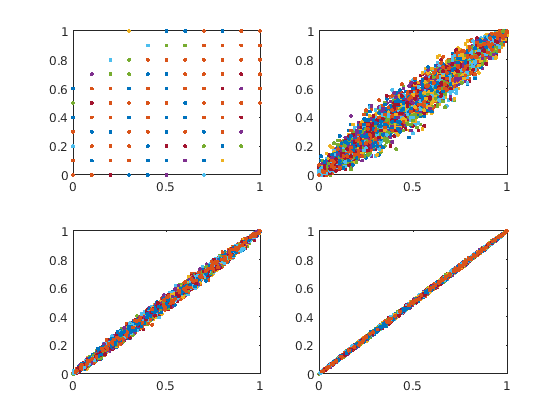

figure;
for i=1:length(permutation_matrix)
    subplot(2,2,i);
    plot(permutation_matrix{i}, Cpermutation_matrix{i}, '.');    
end

**(2.5)** Plot, as a function of the number of iterations, pearson correlation coefficients between the p value matrices generated with algorithms (2.2) and (2.3). Interpret the observed relationship.

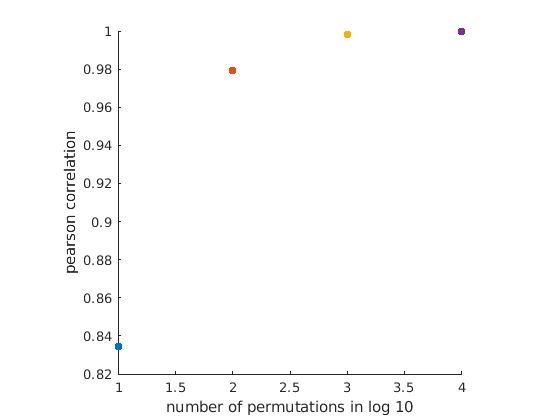

figure, hold on
permutations = [1 2 3 4];
for i = 1:4
    n = permutations(i);
    noteye = ~eye(100);
    plot(n, corr(Cpermutation_matrix{i}(noteye), permutation_matrix{i}(noteye)), '.', 'markersize', 20)
    xlabel('number of permutations in log 10')
    ylabel('pearson correlation')
    axis equal; axis square
end

The correlation tends to asymptopically increase as the number of permutation increases. This makes sense because we should get closer to the true distribution as N increases. This goes hand in hand with the answer for 1.5. 